# Fundamentals of Linear Control

**Mauricio de Oliveira**

*Supplemental material for Chapter 3*

## Before You Start

In this script you will perform calculations associated with rational functions. In addition to the commands already used, the following MATLAB commands will be used:

- `laplace `and `ilaplace,` to calculate (symbolic) Laplace transforms;

- `residue,` to calculate a partial-fraction expansion;

 You will also use the following auxiliary commands:

- `dirac` and `heaviside`, to represent (symbolic) impulse and step functions.

## 3.1 The Laplace Transform

You can use the symbolic toolbox to calculate Laplace transforms in MATLAB. For example:

syms t s % t and s are now a symbolic variables
f = exp(-t) * cos(2 * t);
F = laplace(f, t, s)

$$F = \frac{s+1}{{\left(s+1\right)}^{2}+4}$$

You can also calculate the inverse Laplace transform:

ilaplace(F, s, t)

$$ans = \cos\left(2\,t\right)\,{\mathrm{e}}^{-t}$$

Impulses:

laplace(dirac(t), t, s)

$$ans = 1$$

and steps:

laplace(heaviside(t), t, s)

$$ans = \frac{1}{s}$$

are fine. MATLAB also knows many of the properties and tricks you also know:

F = exp(-s)/(s + 1)

$$F = \frac{{\mathrm{e}}^{-s}}{s+1}$$

ilaplace(F, s, t)

$$ans = \mathrm{heaviside}\left(t-1\right)\,{\mathrm{e}}^{1-t}$$

## 3.5 Rational Functions

Standard MATLAB (not the symbolic toolbox) have a number of functions specialized to polynomial and rational functions. Polynomials are represented by their coefficients. The vectors:

num = [2]

num = 2

den = [1 2 2]

den =      1     2     2


can be used to represent the numerator and denominator of the rational function:


$$F(s) = \frac{2}{s^2 + 2 s + 2}$$


which is our example at the end of Section 3.5.

For example:

[r,p,k] = residue(num, den)

r =    0.0000 - 1.0000i
   0.0000 + 1.0000i


p =   -1.0000 + 1.0000i
  -1.0000 - 1.0000i



k =

     []



calculates its partial-fraction expansion. `r` contain the residues and `p` the correponding poles. In this case this partial-fraction leads to the inverse Laplace transform:


$$f(s) = j e^{(-1 -j) t} - j e^{(-1+j)t} = 2 \sin(t) e^{-t}, \quad t \geq 0$$


as show in Section 3.5. The output parameter `k` contains the remaining polynomial when $F(s)$ is not strictly proper. For example, for 


$$F(s) = \frac{s-1}{s+1} = 1-\frac{2}{s+1}$$


num = [1 -1]

num =      1    -1


den = [1 1]

den =      1     1


[r,p,k] = residue(num, den)

r = -2

p = -1

k = 1

has a non-zero polynomial *remainder *$r = 1$.

For another example, calculate the closed-loop response of the linear car model to a ramp target velocity with slope $\mu = 12$mph/s done in Section 3.5. Define the parameters:

% Linearized car model
pOverBHat = 73.3;
bOverMHat = 0.05;
pOverMHat = pOverBHat * bOverMHat;

For a given

k = 0.02

k = 0.0200

calculate the coefficients

a1 = bOverMHat + k * pOverMHat

a1 = 0.1233

b1 = k * pOverMHat

b1 = 0.0733

The close-loop response to a ramp of slope $\mu$ is the inverse Laplace transform of the transfer-function:


$$Y(s) = \frac{\mu \, b_1}{s^2(s + a_1)}$$


which can be calculated using residues as in:

mu = 12

mu = 12

num = mu * b1

num = 0.8796

den = [1 a1 0 0]

den =     1.0000    0.1233         0         0


[r,p,k] = residue(num, den)

r =    57.8574
  -57.8574
    7.1338


p =    -0.1233
         0
         0



k =

     []



which can be used to construct the response

T = 15;
t = linspace(0,T,100);
y = r(1) * exp(p(1) * t) + r(2) * exp(p(2) * t) + r(3) * exp(p(3) * t) .* t;

Plot the response:

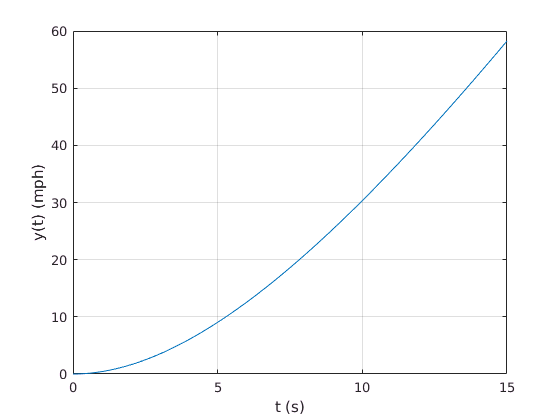

plot(t, y)
xlabel('t (s)')
ylabel('y(t) (mph)')
grid on

Calculate the closed-loop response and the steady-state part of the response of the linear car model to a ramp target velocity with slope $\mu = 12$mph/s for various values of gain:

yBar = 60

yBar = 60

N = 4;
ks = [0 0.02 0.05 0.5];

yy = zeros(2*(N-1), length(t));
for i = 2 : N

  k = ks(i);

  b1 = k * pOverMHat;
  a1 = bOverMHat + k * pOverMHat;

  % response using residues
  num = mu * b1;
  den = [1 a1 0 0];
  [r,p,k] = residue(num, den);
  yy(i-1,:) = r(1) * exp(p(1) * t) + r(2) * exp(p(2) * t) + r(3) * exp(p(3) * t) .* t;

  % steady-state response:
  yy(N+i-2,:) = r(2) * exp(p(2) * t) + r(3) * exp(p(3) * t) .* t;

end

and plot the responses:

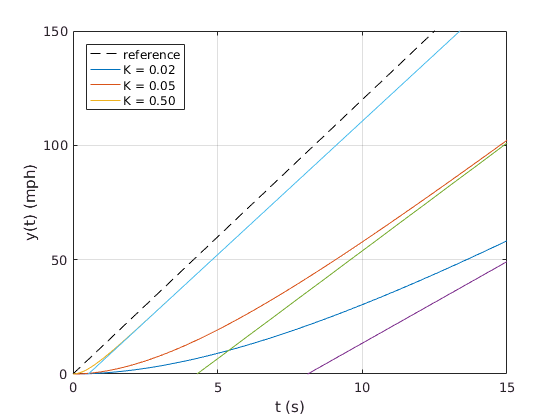

% Fig. 3.3:
figure()
plot([0 T], [0 mu*T], 'k--', t, yy, '-')
xlabel('t (s)')
ylabel('y(t) (mph)')

leg = [char(ones(N, 1) * double('K = ')) num2str(ks','%3.2f') char(ones(N, 1) * double(' '))];
leg(1,:) = 'reference';
legend(leg,'Location','NorthWest')

ylim([0 150]);
grid